% Load IBS data
load('F:\data\VALIDEIT09\eit\MIK_P_O\eitV2.mat');
crs = NonInvEIT(eit);

imgFilt = applyFilter(crs,crs.ImgRaw,crs.Fs,false);
imgFilt(isnan(imgFilt)) = 0;

load('F:\data\VALIDEIT09\eit\cct.mat');

t = crs.T;

playVideo(imgFilt);

heartPix = [16,30];
lungPix = [30,40];

heartSig = squeeze(imgFilt(heartPix(1),heartPix(2),:));
lungSig = squeeze(imgFilt(lungPix(1),lungPix(2),:));

figure; plot(t, [heartSig,lungSig]);
xlabel('Time [s]'); ylabel('Relative Impedance [a.u.]');
legend(["Heart","Lung"]);
title("Raw EIT signal - VRS and CRS mixed");

[~,mask] = spatialDenoise(imgFilt);
flatIdx = find(mask);
[idxX,idxY] = ind2sub([size(mask,1),size(mask,2)],flatIdx);
imgIdx = [idxX,idxY];

flatImg = reshape(imgFilt,64*64,[]);
flatImg = flatImg(flatIdx,:); 

dataWin = 100;
X = flatImg(:,1:dataWin-2);
X(isnan(X)) = 0;
Y = flatImg(:,2:dataWin-1);
Y(isnan(Y)) = 0;

% Initialize DMD class and properties
dmd = DMD();
rank = 58; % rank to truncate data to
predHor = dataWin + 1; % prediction horizon (in samples)
tSim = (1:predHor)'/crs.Fs + t(end);

% Modified Exact DMD
tic
fitKoopman(dmd, X, Y, rank, predHor);
fitModes(dmd, X, Y, crs.Fs, 'exact-mod');
cleanModes(dmd);
interpModes(dmd);
toc

% Corrected frequency plot
powSpect(dmd, reshape(imgFilt,size(imgFilt,1) * size(imgFilt,2), [])', crs.Fs);

rank = -1;

tStart = 10;
tEnd = 13;
data = imgFilt(:,:,(tStart * crs.Fs):(tEnd * crs.Fs));
flatImg = reshape(data,size(data,1) * size(data,2), []);

predHor = size(data,3)+1;

Xout = hankelTransform(dmd,flatImg(:,1:end-1), 5);
Yout = hankelTransform(dmd,flatImg(:,2:end), 5);

tic
fitKoopman(dmd, Xout, Yout, rank, predHor);
fitModes(dmd, Xout, Yout, crs.Fs, 'hankel');
[Xcomps, Xtotal] = reconData(dmd, predHor, 1, 'disc');
cleanModes(dmd);
interpModes(dmd);
toc
XtotalImg = reshape(real(Xtotal(1:4096,:)),64,64,[]);

playVideo(XtotalImg)
lung = squeeze(data(lungPix(1),lungPix(2),:));
lungRecon = squeeze(XtotalImg(lungPix(1),lungPix(2),:));
figure; plot(lung); hold on; plot([lungRecon]);

% SIGNAL PREPARATION
flatImg = reshape(imgFilt,64*64,[]);

[~,mask] = spatialDenoise(imgFilt,0.1);
mask(isnan(mask)) = 0;
flatIdx = find(mask);
[idxX,idxY] = ind2sub([size(mask,1),size(mask,2)],flatIdx);
imgIdx = [idxX,idxY];

% INITIALIZATION
rank = -1;
halfLife = 1 * crs.Fs;
rho = 2 ^ (- 1 / halfLife);

wInit = 5;
tStart = 10; nStartInit = floor(tStart * crs.Fs + 1);
tEnd = wInit + tStart; nEndInit = ceil(tEnd * crs.Fs);

data = imgFilt(:,:,nStartInit:nEndInit);
flatImg = reshape(data,size(data,1) * size(data,2), []);

predHor = size(data,3)+1;

dmd = DMD();

% X = flatImg(flatIdx,1:end-1);
% Y = flatImg(flatIdx,2:end);

X = hankelTransform(dmd,flatImg(flatIdx,1:end-1), 5);
Y = hankelTransform(dmd,flatImg(flatIdx,2:end), 5);

fitKoopman(dmd, X, Y, rank, predHor, 'stream');

fitModes(dmd, X, Y, crs.Fs, 'vanilla');

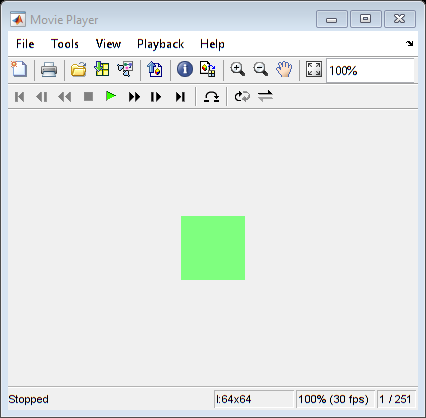

ans =   UnifiedScope with properties:

    InstanceNumber: 5
     Specification: [1×1 iptscopes.IMPlayScopeCfg]
        MessageLog: []
            Visual: [1×1 iptscopes.VideoVisual]
        DataSource: [1×1 matlabshared.scopes.source.WorkspaceSource]
            Parent: [1×1 Figure]


[Xcomps, Xtotal] = reconData(dmd, predHor, crs.Fs, 'disc');
cleanModes(dmd);
interpModes(dmd);

flatImgRecon = zeros(size(flatImg,1),size(Xtotal,2));
flatImgRecon(flatIdx,:,:) = Xtotal(1:length(flatIdx),:);
XtotalImg = reshape(real(flatImgRecon),64,64,[]);

playVideo(XtotalImg)

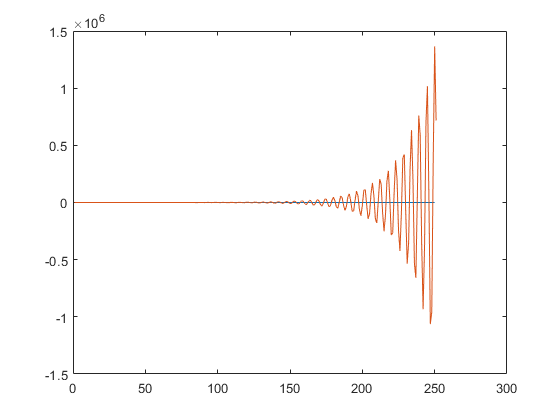

lung = squeeze(data(lungPix(1),lungPix(2),:));
lungRecon = squeeze(XtotalImg(lungPix(1),lungPix(2),:));
figure; plot(lung); hold on; plot([lungRecon])

% try one update
w = 0.5; % s 
nW = floor(w * crs.Fs);
del = 100; % ms
nDel = floor(del * crs.Fs / 1000);

flatImg = reshape(imgFilt,size(imgFilt,1) * size(imgFilt,2), []);

nStart = nEndInit + 1; 
nEnd = size(imgFilt,3) - nW;

i = nStart

i = 751

if nDel ~= 0
    Xnew = hankelTransform(dmd,flatImg(flatIdx,i:i + nW - 1), nDel);
    Ynew = hankelTransform(dmd,flatImg(flatIdx,i + 1:i + nW), nDel);
else
    Xnew = flatImg(flatIdx,i:i + nW - 1);
    Ynew = flatImg(flatIdx,i + 1:i + nW);
end


tic
updateStream(dmd, Xnew, Ynew, rho);

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Error in DMD/updateStream (line 144)
            xtilde = obj.Ux' * x;

toc

fitModes(dmd, X, Y, crs.Fs, 'vanilla');
[~, Xtotal] = reconData(dmd, nW, crs.Fs, 'disc'); 
    
Xfinal = zeros(size(flatImg,1),size(Xtotal,2));
Xfinal(flatIdx,:) = Xtotal(1:length(flatIdx),:);

XtotalImg = reshape(real(Xfinal),64,64,[]);
playVideo(XtotalImg);
lung = squeeze(imgFilt(lungPix(1),lungPix(2),i + 1:i + nW));
lungRecon = squeeze(XtotalImg(lungPix(1),lungPix(2),:));
figure; plot(lung); hold on; plot([lungRecon])

w = 2; % s 
nW = floor(w * crs.Fs);
del = 100; % ms
nDel = floor(del * crs.Fs / 1000);

flatImg = reshape(imgFilt,size(imgFilt,1) * size(imgFilt,2), []);

nStart = nEndInit + 1; 
nEnd = size(imgFilt,3) - nW;
% 
% blocks1 = zeros(nW,nEnd);
% blocks2 = zeros(nW,nEnd);

Xfinal = zeros(size(flatImg,1),nEnd);
compTime = zeros(nEnd,1);
for i = nStart:nEnd
%     block1 = heartSig(i:i + nW - 1);
%     blocks1(:,i) = block1;
%     
%     block2 = heartSig(i + 1:i + nW);
%     blocks2(:,i) = block2;
    
    Xnew = hankelTransform(dmd,flatImg(flatIdx,i:i + nW - 1), nDel);
    Ynew = hankelTransform(dmd,flatImg(flatIdx,i + 1:i + nW), nDel);
    
    tic
    updateStream(dmd, Xnew, Ynew, rho);
    compTime(i) = toc;
    
    fitModes(dmd, X, Y, crs.Fs, 'vanilla');
    [~, Xtotal] = reconData(dmd, nW, crs.Fs, 'disc'); 
    
    Xfinal(flatIdx,i) = Xtotal(1:length(flatIdx),end);
end

% RUNNING WINDOW
% Define sliding window length
% Define window weights based on half-life

times = [];
signal = [];
for i = initStart + 1:size(flatImg,2) - 20
    % Build Hankel
    
    Xnew = flatImg(flatIdx,i);
    Ynew = flatImg(flatIdx,i + 20);
    
    tic
    updateStream(dmd, Xnew, Ynew, rho); % include Atilde update in updateStream + make rank property
    et = toc;
    
    [~, Xfinal] = reconData(dmd, 1, crs.Fs, 'cont');
    
    signal = [signal,Xfinal];
    times = [times;et];
end

% SIGNAL PLOTTING
flatImgRecon = zeros(size(imgFilt,1),size(imgFilt,2),size(signal,2));
flatImgRecon(flatIdx,:,:) = signal;

figure; plot(times)
finalSignal = real(reshape(flatImgRecon,64,64,[]));
playVideo(finalSignal)



for k = w+1:m
   tic
     sdmd2.update(X1(:,k),X2(:,k)); %update step
      
    %%%only for recon error
     [modes, lambda] = sdmd2.modes;
     b = pinv(modes)*X2(:,k);
    
      for j = 1:20
      
        tmp = lambda(j) * b(j) * modes(:,j);
        
        Xcomps{j}(:,k+1) = tmp;
        Xdmd(:,k+1) = Xdmd(:,k+1) + tmp;
        Xdmd(:,k+1) = tmp;
    end
    
   
   elapsed_time(k) = toc;
end